# Finite Precision Effects in IIR and FIR Filters (200 Points)

Dear Students, 

Welcome to Lab 5!

In all the previous labs, you have used **double precision floating point data types **(although we explicitly never mentioned it)**.**  Now, read: [https://in.mathworks.com/help/matlab/matlab_prog/floating-point-numbers.html](https://in.mathworks.com/help/matlab/matlab_prog/floating-point-numbers.html) and answer the following: 

- What are the maximum and minimum numbers that you can represent using double precision floating point data types? 

            *ANSWER HERE *`  |2.22507e-308|<number<|1.79769e+308| where number is the number to be represented.`

- Can you represent all the possible real numbers using the double precision data type? With what accuracy? 

          * ANSWER HERE No any number greater than than *`|1.79769e+308| can't be represented as that is treated as infinity . Also any 0<number <|2.22507e-308| can't be represented.`

In practice, most of the time, we will need to implement filters using registers and processors which can store and process, respectively, a finite number of bits. Hence, we need to quantize the data and filter coefficients. In this lab, we will study how the filter characteristics get affected when we quantize them. 

### References: 

-  [https://spinlab.wpi.edu/courses/ece503_2014/week9.html](https://spinlab.wpi.edu/courses/ece503_2014/week9.html)                                                                                                                 

             **Please go through **[**https://spinlab.wpi.edu/courses/ece503_2014/9dot1.mp4,**](https://spinlab.wpi.edu/courses/ece503_2014/9dot1.mp4,)** without fail.** 

-  "A.V. Oppenheim and R. W. Schafer, Discrete-Time Signal Processing, Prentice Hall": Chapter 6, Section 6.1 and Section 7 of the 2nd Edition or Chapter 6, Section 7.1 and Section 8 of the 3rd Edition. 

### Learning Outcomes: 

At the end of the lab, you will be able to

- Explain 2's complement fixed point number representation

- Explain how the pole and zero locations, and the filter characteristics change in the IIR Filters due to coefficient quantization. 

- Explain how the zero locations and the filter characteristics change in the FIR filters due to coefficient quantization. 

## 2's-Complement Fixed Point Number Representation: 

Consider a register which stores $B+1$bits, $b_0 b_1,\ldots,b_{B-q}b_{B-q+1}b_B$, in the 2's-complement notation. The **decimal number** it represents (this is **what the processor sees) **is the** integer: **$-b_02^B+\sum_{i=1}^Bb_i2^{B-i}$. In the fixed-point representation, a register will not store the decimal or the binary point location. 

Now, as a programmer, you can **imagine **that the binary point is between $b_{B-q}$ and $b_{B-q+1}$, i.e, imagining $b_0 b_1,\ldots,b_{B-q\diamond}b_{B-q+1}b_B$, where $_\diamond$ denotes the binary point. In this case,  the number bits after binary points, called as the number of fractional bits, is $B-q$ bits. We can now interpret the number stored to be the decimal number:  $\hat{x}_B  = 2^{-(B-q)}\left(-b_02^B+\sum_{i=1}^Bb_i2^{B-i}\right)=2^{q}\left( -b_0+\sum_{i=1}^Bb_i2^{-i}\right)$.  With this imagined binary point, you as a programmer must take care of carrying out consistent arithmetic (addition and multiplication) operations, while the computer is interpreting the number as an integer.

- Suppose $\hat{x}_B = 1_\diamond 0101$in the 2's-complement format, what decimal number does it represent? 

             **ANS:** -11 (integer) or 0.6975 (floating point)

- Suppose $\hat{x}_B = 0_\diamond 0101$in the 2's-complement format, what decimal number does it represent? 

**            ANS:** $5$(integer) or 1.6975(floating point)

- Quantize 1/3 (in decimal) to 4 bits, using  (i) Rounding, and (ii) Truncation

                ** Rounding:** 0.011  (in Binary) =0.375 (in decimal)

                 **Truncation:** $0\ldotp 010$  (in Binary)=0.25(In Decimal)

## Finite Precision Effects in IIR Filters 

Let us design and quantize filter coefficients and analyse the impact of quantization on filter characteristics. We are using the example given in [https://spinlab.wpi.edu/courses/ece503_2014/9-3coefficient_quantization_iir.pdf](https://spinlab.wpi.edu/courses/ece503_2014/9-3coefficient_quantization_iir.pdf)

Our requirements are given below. 

Fpass = 0.2; % Passband Frequency
Fstop = 0.25; % Stopband Frequency
Apass = 1; % Passband Ripple (dB)
Astop = 60; % Stopband Attenuation (dB)
match = 'both';

  Now, we can either go the  *filterDesigner *to design the filter or we can design the filter using the code below. Look at [https://in.mathworks.com/help/dsp/ref/fdesign.lowpass.html](https://in.mathworks.com/help/dsp/ref/fdesign.lowpass.html) for more details on this method. 

h = fdesign.lowpass('Fp,Fst,Ap,Ast',Fpass, Fstop, Apass, Astop); % Create a lowpass filter specification object
Hd = design(h, 'ellip', 'MatchExactly', match);  % 
[b, a] = tf(Hd);             % Extract the filter coef

% Display as a table
Coef_Double_Prec = table(b', a');
Coef_Double_Prec.Properties.VariableNames = {'b','a'};
Coef_Double_Prec.Properties.Description = 'The filter coefficients  in double-precision floating point format'

Coef_Double_Prec = 8×2 table
        b            a    
    __________    ________

      0.002567           1
    -0.0063435      -5.676
     0.0086181      14.495
    -0.0036387     -21.459
    -0.0036387      19.833
     0.0086181     -11.425
    -0.0063435      3.7981
      0.002567    -0.56257


Now assume that we have $B+1 = 8$bit register to store and implement the filter. Observe the coefficients, $b$ and $a$. 

- Can you represent all the coefficients in 8 bits?   ANS Not exactly

                b=[0.00000000, 1.0000001, 0.0000001, 1.0000000, 1.0000000, 0.0000001, 1.0000001, 0.0000000 ] **For b=> M.S.B 1 means -ve number**  =>b=[0, -0.008, 0.008, -0, -0, 0.008, -0.008, 0 ]

                a=[000001.00, 100101.1, 001110.01,110101.01, 010011.11, 101011.01, 000011.11, 100000.10]  **For a => M.S.B 1 means -ve number** =>a=[1, -5.5, 14.25, -21.25,  19.75, -11.25, 3.75, -0.5]

- What is the dynamic range of denominator coefficient, $a$? ANS ...41.292   will need[-32 +32] range to represent.

-   That is, what is $\frac{\max\{|a|\}}{\min\{|a|\}}$?  ANS ... =**38.143**

### One-Shot Direct-Form Realizations  (75 Points)

Now, let us quantize these coefficients to $8$bit 2's complement format. In the below, we will assume that all the elements in $a$ and $b$ will be represented by same number of fractional bits (can be different for $a$ and $b$). We will first identify the minimum number of bits required for representing the non-fractional part of the  maximum number: In this case, there will not be saturation of any of the coefficients. However, there will be huge rounding errors. 

B_qa = [5];   % FILL IN THE BLANKS: Compute the minimum number of bits required for representing the
% non-fractional part of the maximum value in the "a" coefficients. 
B_qb = [0];  % FILL IN THE BLANKS: Compute the minimum number of bits required for representing the
% non-fractional part of the maximum value in the "b" coefficients. 

B = 7;   % 8 bit register is available. So B =7 (see the previous section about 2's complement notation)   
qa = [2]; % FILL IN THE BLANKS:  Number of bits available for denoting the fraction part of "a" coefficients
qb = [7];  % FILL IN THE BLANKS:  Number of bits available for denoting the fraction part of "b" coefficients
aHat = [round(a*2^qa)/2^qa]; % FILL IN THE BLANKS: Quantized "a"
bHat = [round(b*2^qb)/2^qb];  % FILL IN THE BLANKS: Quantized "b"
% aHat=[1, -5.5, 14.25, -21.25,  19.75, -11.25, 3.75, -0.5]; % FILL IN THE BLANKS: Quantized "a"
% bhat=[0, -0.008, 0.008, -0, -0, 0.008, -0.008, 0 ]; % FILL IN THE BLANKS: Quantized "b"
Coef_8bit_fixed_point = table(b', bHat', bHat'*2^qb, a', aHat', aHat'*2^qa);
Coef_8bit_fixed_point.Properties.VariableNames = {'b','bHat','bHat for Computer'  ,'a', 'aHat','aHat for Computer'};
Coef_8bit_fixed_point.Properties.Description = 'The filter coefficients in double-precision floating point format'

Coef_8bit_fixed_point = 8×6 table
        b            bHat       bHat for Computer       a        aHat     aHat for Computer
    __________    __________    _________________    ________    _____    _________________

      0.002567             0            0                   1        1             4       
    -0.0063435    -0.0078125           -1              -5.676    -5.75           -23       
     0.0086181     0.0078125            1              14.495     14.5            58       
    -0.0036387             0            0             -21.459    -21.5           -86       
    -0.0036387             0            0              19.833    19.75            79       
     0.0086181     0.0078125            1             -11.425    -11.5           -46       
    -0.0063435    -0.0078

Now, obtain the frequency response and the pole-zero plot of the original and quantized filters: 

- Frequency response of the original filter is:

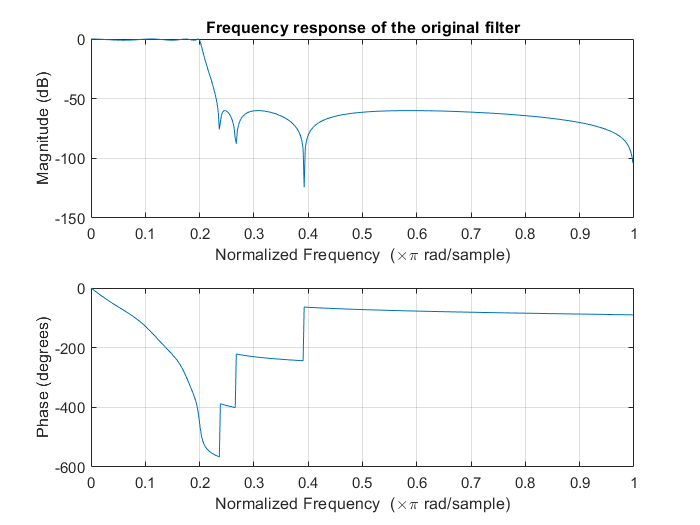

freqz(b,a)
title("Frequency response of the original filter")% ENTER YOUR CODE HERE

- Pole-zero plot of the original filter is:

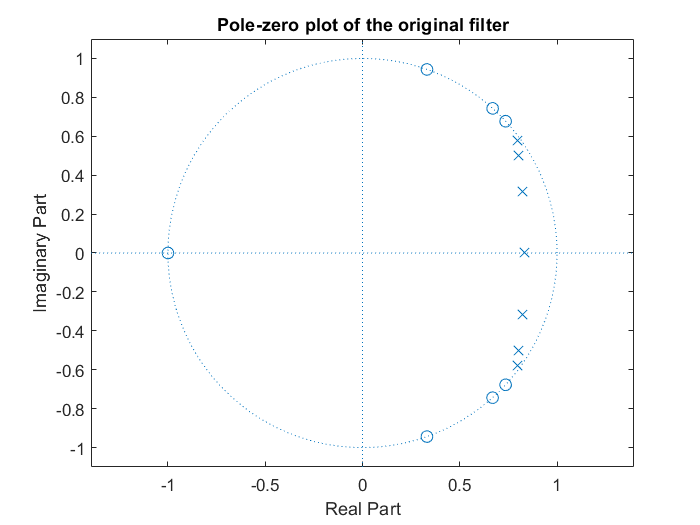

zplane(b,a)
title("Pole-zero plot of the original filter")% ENTER YOUR CODE HERE

- Frequency response of the quantized filter is:

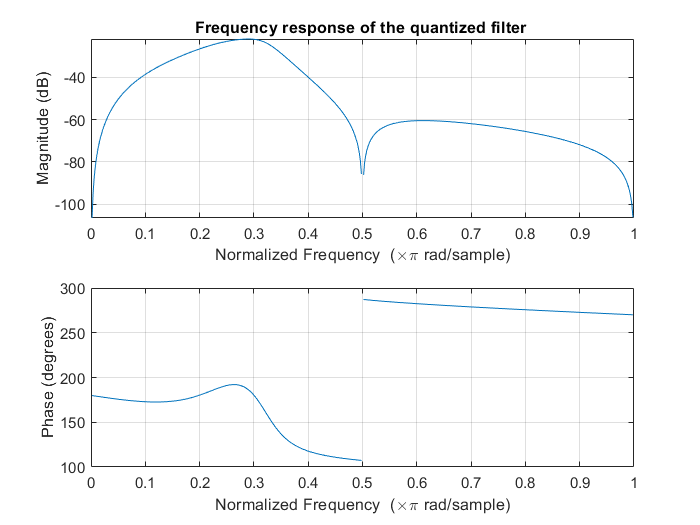

freqz(bHat,aHat)
title("Frequency response of the quantized filter ")% ENTER YOUR CODE HERE

- Pole-zero plot of the quantized filter is: 

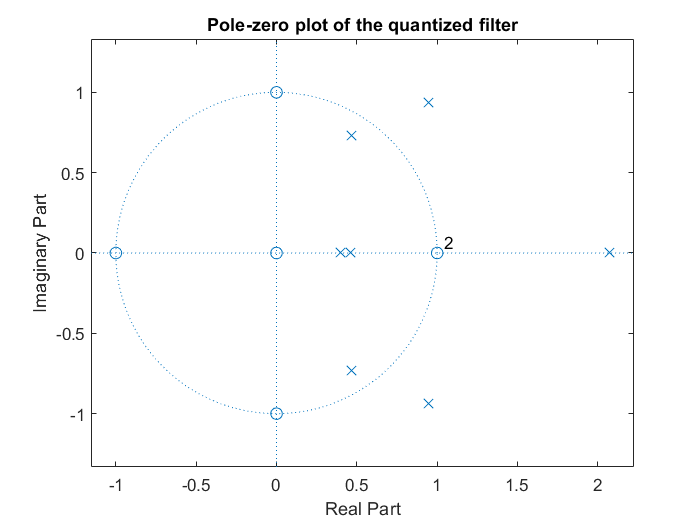

zplane(bHat,aHat)
title("Pole-zero plot of the quantized filter")% ENTER YOUR CODE HERE

**Questions (READ Section 7.2 of the 2nd Edition or Section 8.2 of the 3rd Edition in Chapter 6 of the Textbook for Hints):**

- Comment on the quantized coefficients. Which quantization method did you use?  

          * ANSWER HERE Rounding to closest 8 bit value.*

- Is the new filter with quantized coefficients stable? How does the frequency response compare with the original filter? 

          * ANSWER HERE  The new filter with quantized coefficients is unstable. The frequency response it very different to origional filter.*

- (True/False, If false, correct the statement): Each quantized numerator coefficient changes only a single zero.  

          * ANSWER HERE True*

- (True/False, If false, correct the statement): Each quantized denominator coefficient changes only a single pole.  

           * ANSWER HERE False. (All the poles may get affected by changing the coefficients. )*

- (True/False, If false, correct the statement): Quantizing the numerator coefficients will never make a filter unstable.  

          * ANSWER HERE True , as the poles are responsible for stability . So quantizing only nemerator won't affect stability.*

- Any other observations? 

          * ANSWER HERE (Since I got some poles outside the unit circle that will make the filter unstable.) And the frequency response does not match the origional filter so the quantized filter won't be useful.*

### Cascade Form Realizations: (75 Points)

We called the previous subsection as "One-Shot Direct-Form Realizations". Why is it justified? (Think of how we implement the direct form structures once the coefficients are designed)

          * ANSWER HERE Since we simply build the filter with the coefficients ie. numerator(zeros) and Denominator(poles) without worrying about performance(hardware and computation requirements) .*

In this subsection, we will look at how the quantization of filter coefficients will affect the filter response if we adopt cascade form realization. Specifically, we will focus on the second-order-sections. 

How many second order sections does the filter in the above subsection require?

  * ANSWER HERE It needs 4 Second Order sections*

- Obtain $b $ and $a$ coefficients of each of the second order sections. (Use [tf2sos](https://in.mathworks.com/help/signal/ref/tf2sos.html))

[sosMatrix, gain] = [tf2sos(b,a)]; %FILL IN THE BLANKS:

% Coefficients of the first SOS are
b1 = [sosMatrix(1,1:3)]; % FILL IN THE BLANKS: Enter numerator coef of the first SOS
a1 = [sosMatrix(1,4:6)]; % FILL IN THE BLANKS: Enter denominator coef of the first SOS

% In the below, write down bi and ai for the ith SOS (depending on how many SOS are there)
b2 = [sosMatrix(2,1:3)]; 
a2 = [sosMatrix(2,4:6)]; 
b3 = [sosMatrix(3,1:3)]; 
a3 = [sosMatrix(3,4:6)]; 
b4 = [sosMatrix(4,1:3)]; 
a4 = [sosMatrix(4,4:6)]; 
% FILL IN THE BLANKS



- What is the dynamic range of the coefficients now? Are they greater or smaller compared to those in Direct-Form Realizations

            * ANSWER HERE The dynamic range of coefficients a is 2.47 can be represented by [-2 2 ], for b its 2.64 and can be represented in[-2 2]. SO they are smaller than Direct-Form Realizations. *

- Now quantize (with B=7) each section separately. 

            * ANSWER HERE*

%% ENTER YOUR CODE HERE
B = 7;   % 8 bit register is available. So B =7 (see the previous section about 2's complement notation)   
qa = [6]; % FILL IN THE BLANKS:  Number of bits available for denoting the fraction part of "a" coefficients
qb = [6];  % FILL IN THE BLANKS:  Number of bits available for denoting the fraction part of "b" coefficients
aHat1 = [round(a1*2^qa)/2^qa]; %  Quantized "a1"
bHat1 = [round(b1*2^qb)/2^qb];  %  Quantized "b1"
aHat2 = [round(a2*2^qa)/2^qa]; %  Quantized "a2"
bHat2 = [round(b2*2^qb)/2^qb];  %  Quantized "b2"
aHat3 = [round(a3*2^qa)/2^qa]; %  Quantized "a3"
bHat3 = [round(b3*2^qb)/2^qb];  %  Quantized "b3"
aHat4 = [round(a4*2^qa)/2^qa]; %  Quantized "a4"
bHat4 = [round(b1*2^qb)/2^qb];  % Quantized "b4"


- Obtain the overall filter response of the above filter where each SOS section is quantized separately. 

%% ENTER YOUR CODE HERE
resp=gain*filt(bHat1, aHat1)*filt(bHat2, aHat2)*filt(bHat3, aHat3)*filt(bHat4, aHat4) %To add all SOS sections separately


resp =
 
  0.002567 + 4.337e-19 z^-1 - 0.0003033 z^-2 + 0.004527 z^-3 - 0.0003033 z^-4 + 4.337e-19 z^-5 + 0.002567 z^-6
  ------------------------------------------------------------------------------------------------------------
          1 - 5.672 z^-1 + 14.47 z^-2 - 21.4 z^-3 + 19.76 z^-4 - 11.37 z^-5 + 3.773 z^-6 - 0.5582 z^-7
 
Sample time: unspecified
Discrete-time transfer function.



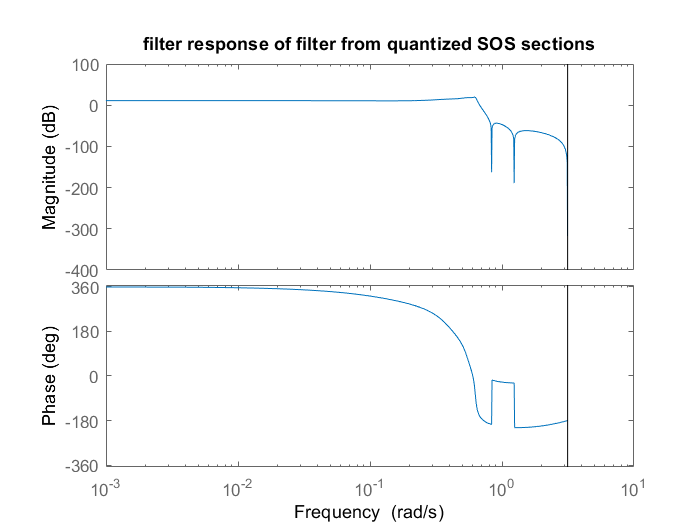

%The filter of that specification will be stored in resp.
bodeplot(resp);
title("filter response of filter from quantized SOS sections")

- Obtain the overall pole-zero plot of the  above filter where each SOS section is quantized separately. 

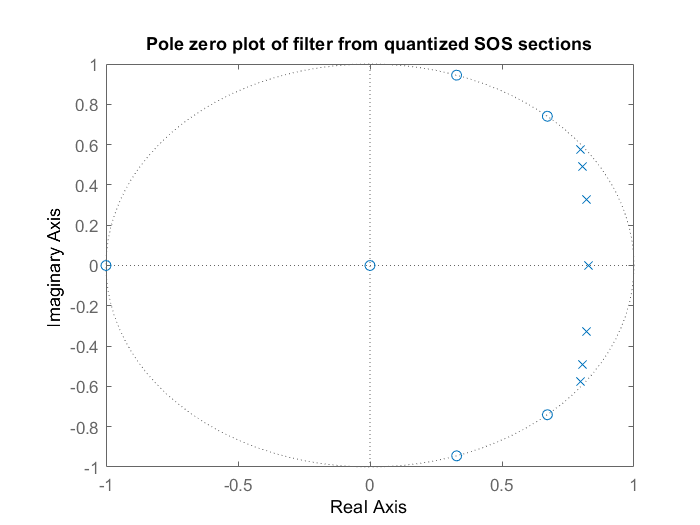

 pzplot(resp)
 title("Pole zero plot of filter from quantized SOS sections")%% ENTER YOUR CODE HERE

- How does the filter response in the quantized Cascade Form compare with that in the One-Shot Direct Form realizations? 

            * ANSWER HERE That is similar though the phase plot is different . Since in this case its plotted using Bode plot so the x asis is log scale and shape looks different but if we see the value of points of transition band and stopband we can find that they both nearly match. So they are similar.*

- How does the pole-zero locations in the quantized Cascade Form compare with that in the One-Shot Direct Form realizations? 

  *            ANSWER HERE The poles are on similar position but zeros are displaced. Both of the pole zero plots are stable so it won't make much difference .*

### Possible Pole Locations in Second-Order Section - Scope for Improvements

In this subsection, we will see, how we can improve implementation of each SOS section. Now, refer to [https://spinlab.wpi.edu/courses/ece503_2014/9-5pole_locations.pdf](https://spinlab.wpi.edu/courses/ece503_2014/9-5pole_locations.pdf)

Note that a single SOS (assuming only poles are present), can be represented as below: 


$$H(z) = \frac{1}{1+Kz^{-1}+Lz^{-2}}$$


Suppose $K$ and $L$ are represented with $B+1=8$ bits and $q_a = 4$ (number of bits used for representing fractional part) 

Now, the possible values $K$and $L$ can take are: 

min=1/2^4; %Denotes the minimum fractional part possible to represent.
% K  = [-8+min:min:8-min];  %This will take really long time to finish. so I
% L = [-8+min:min:8-min];    % just plotted the poles for difference 1.0
%It can take values 0.0625 apart but to keep execution time in limits we
%only take 0.5 gap.
K=[-8+min:0.5:8-min];  %This will make approximation faster within few hours but with less poles in plots than maximum possible.
L=[-8+min:0.5:8-min];

Now, plot all the possible pole locations for the above values of $K$and $L$, along with the unit circle  

% %%%%Uncomment only if want to plot . Have attached plot as image as it took
% %%%%few hours to run otherwise.
% figure
% for i=1:length(K)
%     for j=1:length(L)
%         fil=filt([1],[1 K(i) L(j)]);  %We make the filter
%         pzplot(fil) ;%And plot poles and zeros.
%        %% zplane([1], [1 K(i) L(i)]); %This does not work due with such large limits
%         hold on
%     end
% end
% xlim([-3.5 3.5])
% hold off
% title("All possible pole locations for above values of K & L plot.")

- 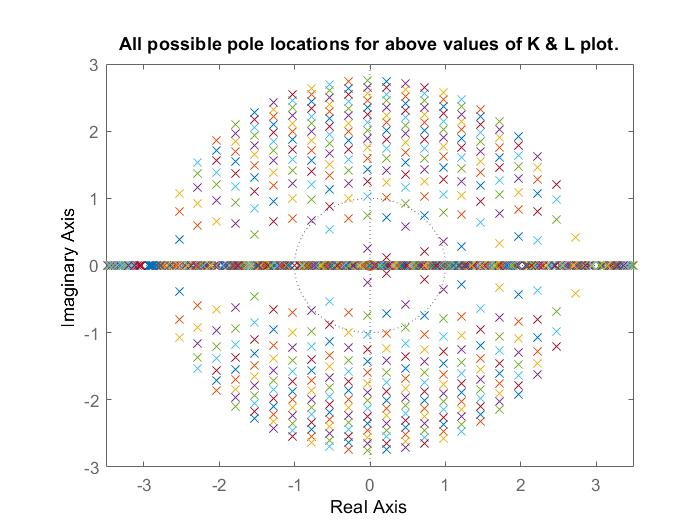

- What are your observations  on the pole locations? Are they evenly spaced? What does this mean in terms of realizing low and high-pass filters when the coefficients are quantized. 

*            ANSWER HERE No they are not evenly spaced and don't cover the region inside the unit circle.So we can't realize all pole locations with this system. (Plotting all possible poles will take very long time so just plotted with spacing 1 as that gives rough idea)*

Now consider the SOS in the Coupled-Form, which appears on Slide 4 of  [https://spinlab.wpi.edu/courses/ece503_2014/9-5pole_locations.pdf.](https://spinlab.wpi.edu/courses/ece503_2014/9-5pole_locations.pdf.) Its system function, 

$H(z) = \frac{\beta}{1-2\alpha z^{-1}+(\alpha^2+\beta^2)z^{-2}}$.

Now, suppose $\alpha$ and $\beta
$ are represented with $B+1=8$ bits and $q_a = 4$ (number of bits used for representing fractional part). The possible values $\alpha$ and $\beta
$ can take are: 

min=1/2^4; %Denotes the minimum fractional part possible to represent using 4 bits.
% alpha  = [-8+min:min:8-min];  %This will take really long time to finish. so I
% beta = [-8+min:min:8-min];    % just plotted the poles for difference 1.0
alpha=[-8+min:0.5:8-min];  %This will make approximation faster within few hours but with less poles in plots than maximum possible.
beta=[-8+min:0.5:8-min]; 

Now, plot all the possible pole locations for the above values of $\alpha$ and $\beta
$, along with the unit circle  

%%%%Uncomment only if want to plot . Have attached plot as image as it took
%%%%few hours to run otherwise.
% figure
% for i=1:length(alpha)
%     for j=1:length(beta)
%         fil=filt([beta(j)],[1 (-2*alpha(i)) (alpha(i)^2+beta(j)^2)]);%We make the filter
%         pzplot(fil) ;%And plot poles and zeros.
%         %zplane([beta(j)],[1 (-2*alpha(i)) (alpha(i)^2+beta(j)^2)]); %won't work too             
%         hold on
%     end
% end
% hold off
% title("All possible pole locations for alpha and beta plot.")% ENTER YOUR CODE HERE. 

- 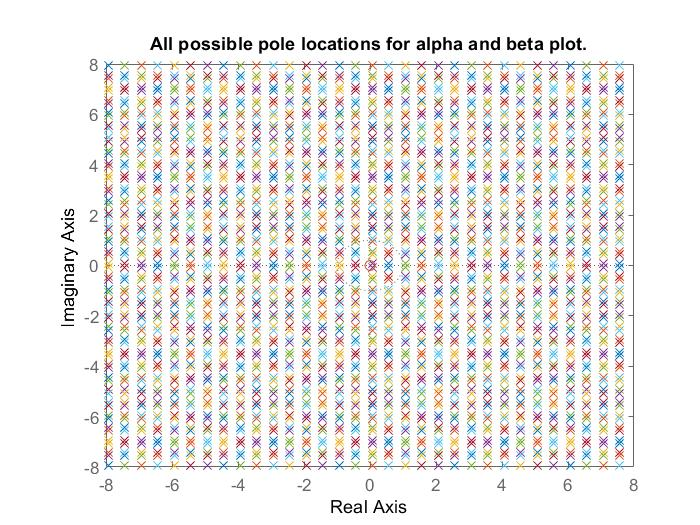

- What are your observations  on the pole locations? Are they evenly spaced? What does this mean in terms of realizing the low and high-pass filters when the coefficients are quantized.  The unit circle is small as compared to the points which cover much larger region.

*            ANSWER HERE Yes this is evenly spaced and cover all pole locations. So we can realize any pole location with it.*

-     Any other observations? 

*            ANSWER HERE This is a very time consuming exercise but I reduced possible values of poles to plot . From the plots we interpret  that SOS in coupled Form is better at representing filters that SOS with Poles.*

## Finite Precision Effects in FIR Filters 

Design a linear-phase FIR filter with the following specifications (Use any method): 

Magnitude response of the designed filter. Order is 9. (FIR Equirriple Filter of minimum order).

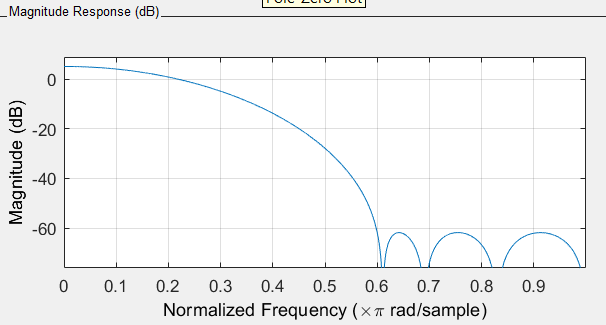

- What is the impulse response of the FIR filter you designed? 

It looks symmetric and maximum at samples 4 and 5.

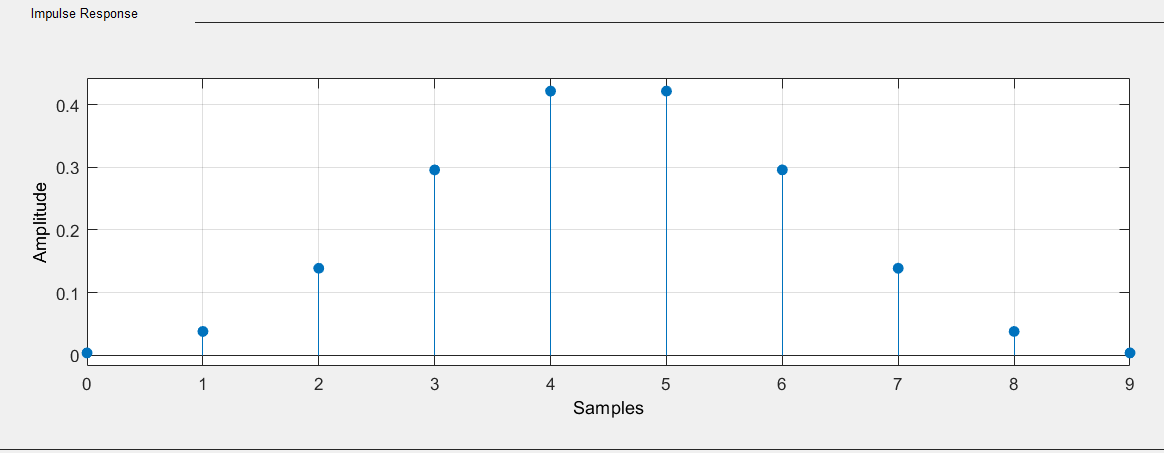

fpass=0.4; %The value is normalized 
fstop=0.6; %normalized stopband
h1  = [0.00359305980174252	0.0378589981255344	0.138777434583630	0.295853057027559	0.421726682085397	0.421726682085397	0.295853057027559	0.138777434583630	0.0378589981255344	0.00359305980174252]; %Filter coefficients (numerator)
h2  = [1]; %FIlter coefficients(denominator)

### One-Shot Director Form Realizations  (50 Points)

- Now, quantize the impulse response to  8 bits (B=7). 

B = 7;   % 8 bit register is available. So B =7  
ha = [6]; % Number of bits available for denoting the fraction part of numerator coefficients
hb = [6];  % FILL IN THE BLANKS:  Number of bits available for denoting the fraction part of "b" coefficients
hHata = [round(h1*2^ha)/2^ha]; %  Quantized numerator coefficient
hHatb = [round(h2*2^hb)/2^hb];  %  Quantized denominator coefficient though its only 1

- Now plot the frequency response of the original filter and the quantized filter. 

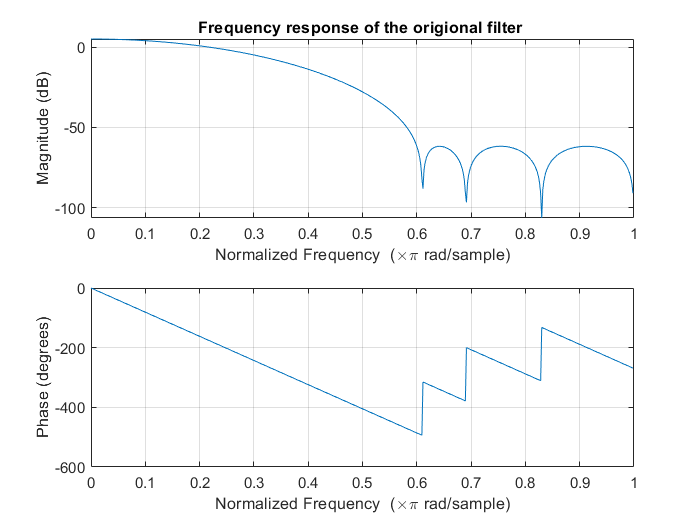

% Magnitude and Phase Response
freqz(h1,h2)
title("Frequency response of the origional filter ") %For origional filter

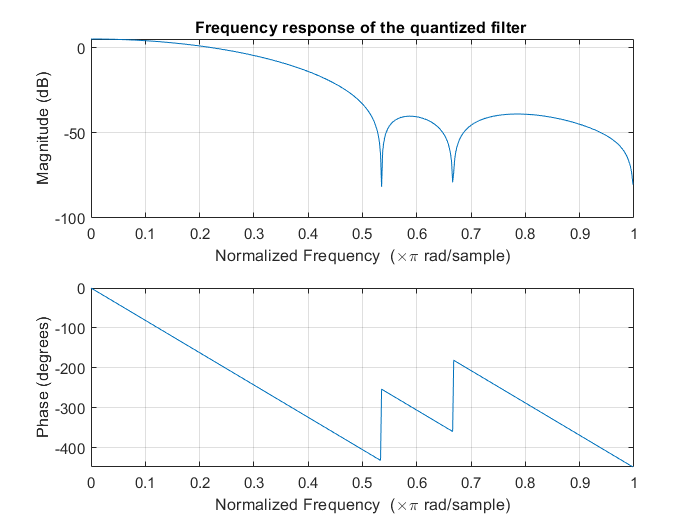

freqz(hHata,hHatb)
title("Frequency response of the quantized filter ")% For quantized filter

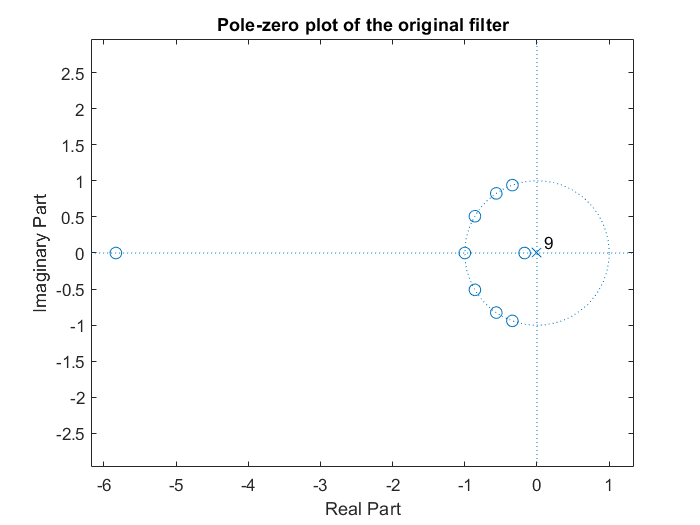

%Pole zero plots
zplane(h1, h2)
title("Pole-zero plot of the original filter") %For origional filter

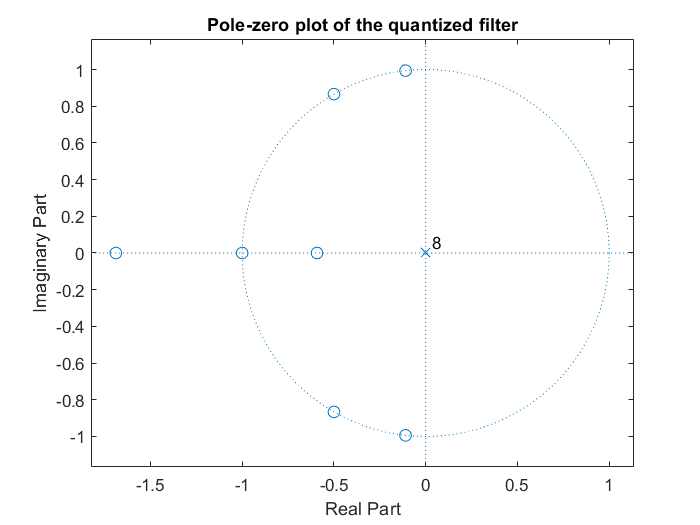

zplane(hHata,hHatb)
title("Pole-zero plot of the quantized filter") %For quantized filter

Now answer the following: 

- How do the frequency responses of the original and quantized filters compare with each other? 

*            ANSWER HERE The frequency responses of origional and quantized filters are similar but the Quantized is scaled (more error). *

- How do the locations of the zeros of the original and quantized filters compare with each other? 

*            ANSWER HERE Both of them are stable (Poles inside unit circle) . But the quantized plot got a pole zero pair less than the origional Pole zero plot.*

- Does the quantized filter maintain its linear phase behavior? 

*            ANSWER HERE Yes both origional and quantized filters are constant linear phase. A zero also came closer to origin but that won't affect anything much.*

### Cascaded Form Realizations (Optional)

Study Section 7.6 of the 2nd Edition or Section 8.6 of the 3rd Edition in Chapter 6 of the Textbook and mention how can we achieve linear-phase when using SOS for implementing an FIR filter. 

In the next lab, we will explore the actual implementation of filters with quantized coefficients and input data. 

## Thank you!